# Laboratorio 2 - Modelo geométrico inverso

**Grupo 8**

Ardila, Juan Andrés

López, Nicolás

Rojas, Juan Camilo

Nuestro robot: Fanuc R-2000iC/125L

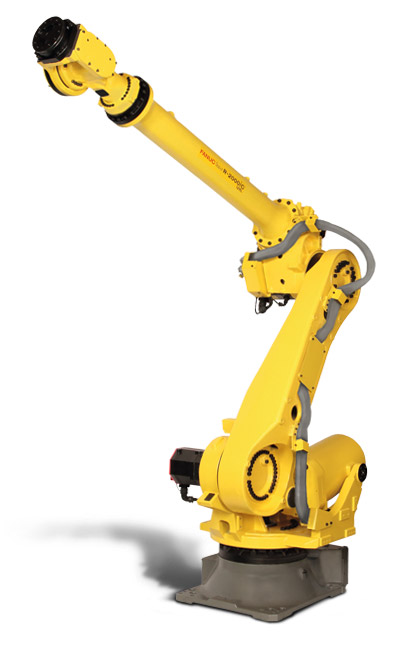

- Determine el modelo geométrico inverso del robot asignado haciendo uso de la metodología explicada en clase. Haga una descripción detallada del proceso haciendo uso de imágenes y dibujos que ayuden visualizar de dónde provienen las ecuaciones encontradas.

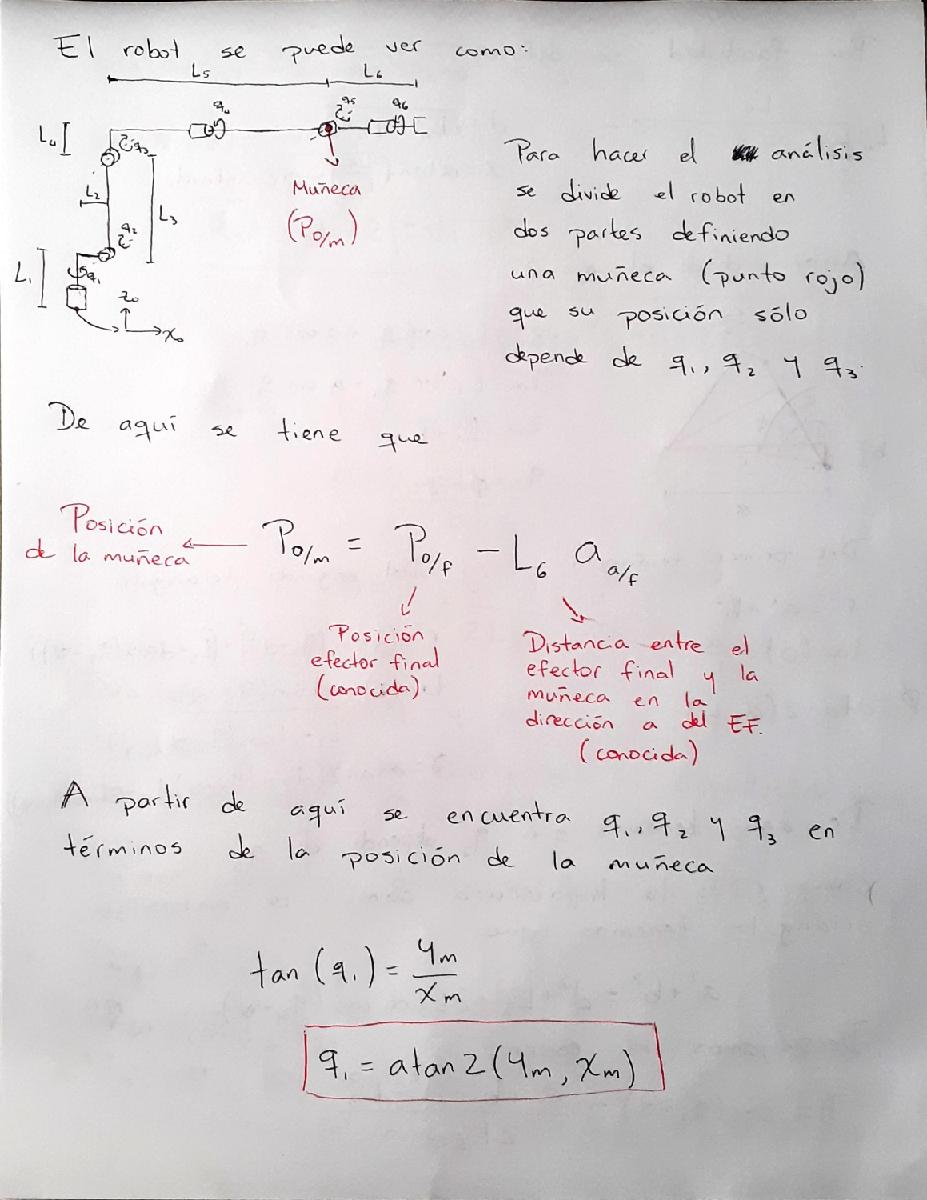

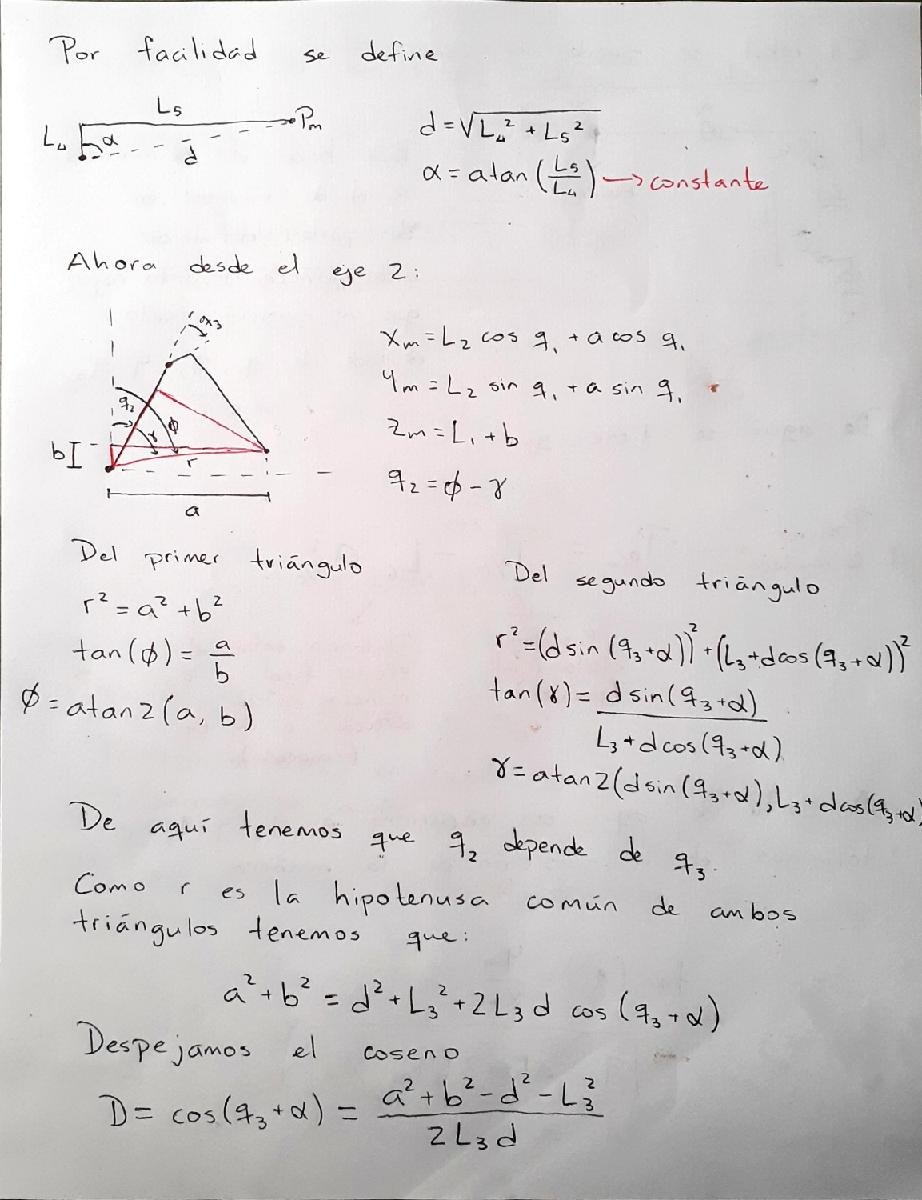

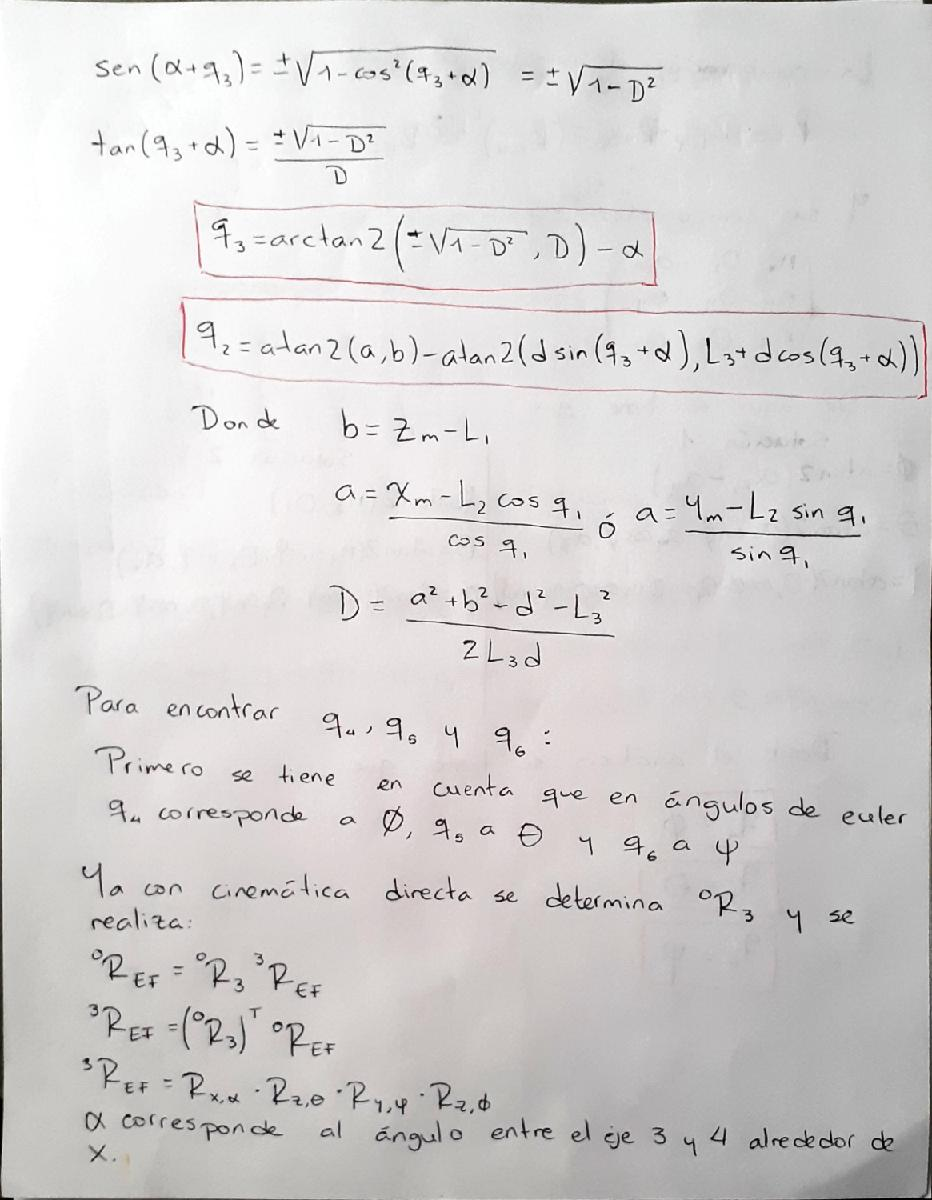

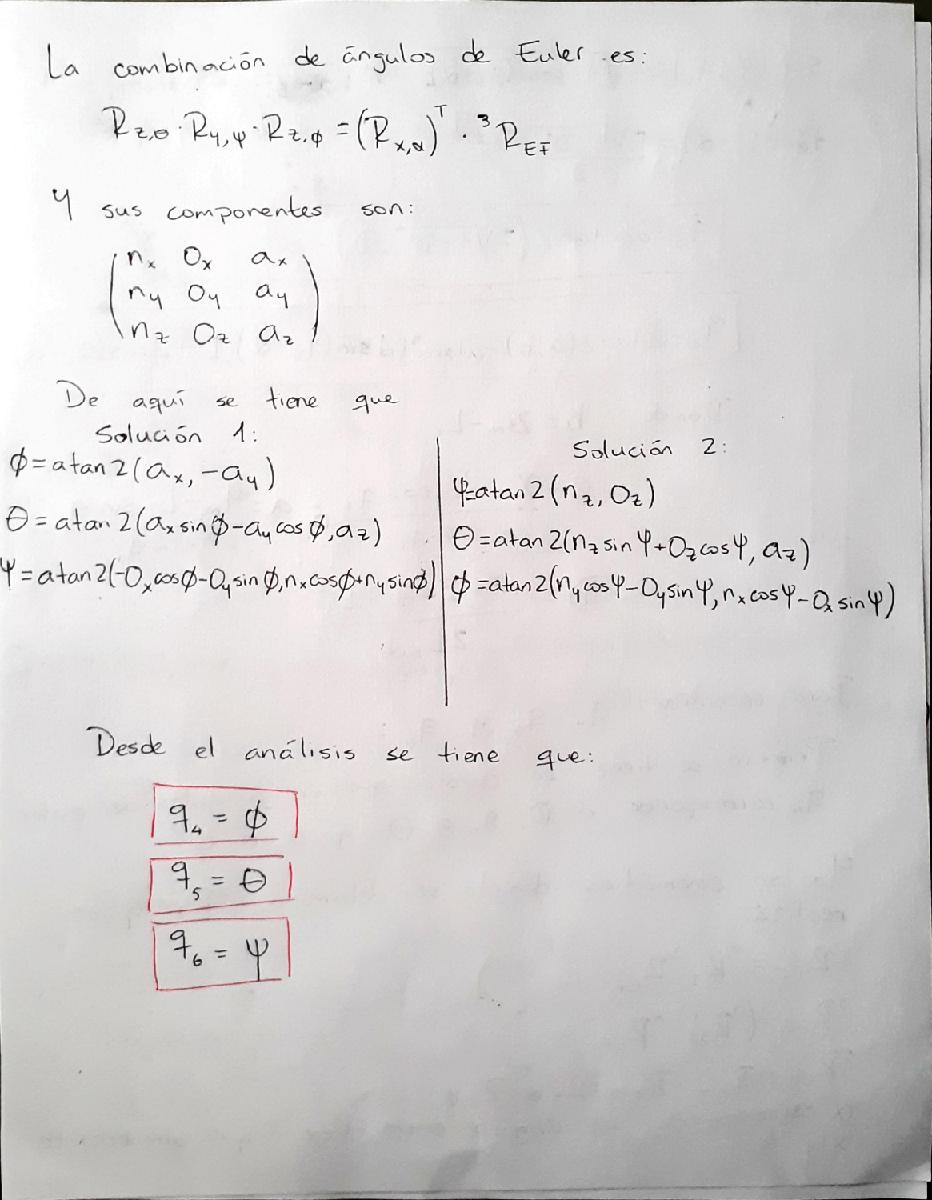

2. En las soluciones de la inversa incluya consideraciones respecto a multiplicidad de soluciones.

Existen al final del análisis dos soluciones para los ángulos de la muñeca, por lo que se puede tener codo arriba y codo abajo. A su vez, si vemos la solución anterior a la muñeca podemos ver que la variable «a» tiene dos soluciones, por lo que puede ser hombro izquierda y hombro derecha. De esta manera tenemos en total 4 soluciones: codo arriba hombro derecha, codo arriba hombro izquierda, codo abajo hombro derecha y codo abajo hombro izquierda.

A continuación veremos el robot como se describió en el laboratorio pasado:

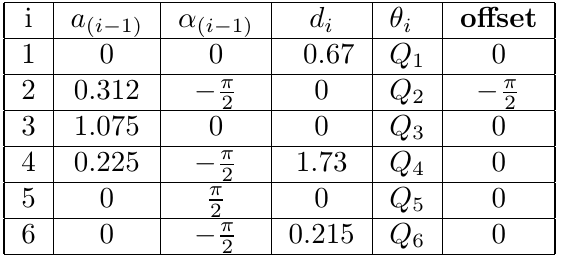

clear
L(1) = Link('revolute','alpha',0,    'a', 0,    'd',0.67, 'offset',0,  ...
    'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha',-pi/2,'a', 0.312,'d',0,    'offset',-pi/2,...
    'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha',0,    'a', 1.075,'d',0,    'offset',0,  ...
    'modified', 'qlim',[-pi pi]);
L(4) = Link('revolute','alpha',-pi/2,'a', 0.225,'d',1.73, 'offset',0, ...
    'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha',pi/2,  'a', 0,   'd',0,    'offset',0, ...
    'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha',-pi/2, 'a', 0,   'd',0.215,'offset',0, ...
    'modified', 'qlim',[-pi pi]);

Robot = SerialLink(L,'name','R_{Fanuc}')

 
Robot = 
 
R_{Fanuc} (6 axis, RRRRRR, modDH, fastRNE)                       
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|       0.67|          0|          0|          0|
|  2|         q2|          0|      0.312|     -1.571|     -1.571|
|  3|         q3|          0|      1.075|          0|          0|
|  4|         q4|       1.73|      0.225|     -1.571|          0|
|  5|         q5|          0|          0|      1.571|          0|
|  6|         q6|      0.215|          0|     -1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0            

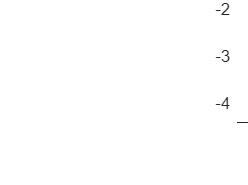

figure(1)
Robot.teach();

La función de cinemática inversa de Peter Coorke no admite utilizar el dhmod, por lo que se hace el mismo robot equivalente en DH estándar.

LS(1) = Link('revolute','alpha',-pi/2,'a', 0.312,'d',0.67, 'offset',0,  ...
    'standard', 'qlim',[-pi pi]);
LS(2) = Link('revolute','alpha',0,    'a', 1.075,'d',0,    'offset',-pi/2,...
    'standard', 'qlim',[-pi pi]);
LS(3) = Link('revolute','alpha',-pi/2,'a', 0.225,'d',0,    'offset',0, ...
    'standard', 'qlim',[-pi pi]);
LS(4) = Link('revolute','alpha',pi/2, 'a', 0,    'd',1.73, 'offset',0, ...
    'standard', 'qlim',[-pi pi]);
LS(5) = Link('revolute','alpha',-pi/2,'a', 0,    'd',0,    'offset',0, ...
    'standard', 'qlim',[-pi pi]);
LS(6) = Link('revolute','alpha',0,    'a', 0,    'd',0.215,'offset',0, ...
    'standard', 'qlim',[-pi pi]);

%Punto de prueba 
T = [0   0  1      0;
     0  -1  0  2.674;
     1   0  0  1.980;
     0   0  0      1];

RobotS = SerialLink(LS,'name','R_{FanucS}')

 
RobotS = 
 
R_{FanucS} (6 axis, RRRRRR, stdDH, fastRNE)                      
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|       0.67|      0.312|     -1.571|          0|
|  2|         q2|          0|      1.075|          0|     -1.571|
|  3|         q3|          0|      0.225|     -1.571|          0|
|  4|         q4|       1.73|          0|      1.571|          0|
|  5|         q5|          0|          0|     -1.571|          0|
|  6|         q6|      0.215|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0           

figure(2)
RobotS.teach();

3.  Haga uso de las funciones del RVC para hallar la cinemática inversa de su robot asignado y compruebe los resultados del punto anterior. Ya que existen varias funciones en el Toolbox explique:

- ¿Cuál es la diferencia entre estas funciones?

- ¿Cuál debe usar para su robot y por qué? (Revise la documentación del Toolbox)

Utilizaremos la función ikine para hacer la cinemática inversa en este caso.

q = RobotS.ikine(T)

q =     1.6510    0.7050   -0.8612    1.5583   -1.6500   -1.7274


Luego comprobamos el resultado utilizando cinemática directa:

AS_0_1 = LS(1).A(q(1))

AS_0_1 =    -0.0801   -0.0000   -0.9968   -0.0250
    0.9968   -0.0000   -0.0801    0.3110
         0   -1.0000    0.0000    0.6700
         0         0         0    1.0000


AS_1_2 = LS(2).A(q(2))

AS_1_2 =     0.6481    0.7616         0    0.6967
   -0.7616    0.6481         0   -0.8187
         0         0    1.0000         0
         0         0         0    1.0000


AS_2_3 = LS(3).A(q(3))

AS_2_3 =     0.6515    0.0000    0.7586    0.1466
   -0.7586    0.0000    0.6515   -0.1707
         0   -1.0000    0.0000         0
         0         0         0    1.0000


AS_3_4 = LS(4).A(q(4))

AS_3_4 =     0.0125   -0.0000    0.9999         0
    0.9999    0.0000   -0.0125         0
         0    1.0000    0.0000    1.7300
         0         0         0    1.0000


AS_4_5 = LS(5).A(q(5))

AS_4_5 =    -0.0792    0.0000    0.9969         0
   -0.9969   -0.0000   -0.0792         0
         0   -1.0000    0.0000         0
         0         0         0    1.0000


AS_5_6 = LS(6).A(q(6))

AS_5_6 =    -0.1560    0.9878         0         0
   -0.9878   -0.1560         0         0
         0         0    1.0000    0.2150
         0         0         0    1.0000



TS_0_6 = AS_0_1 * AS_1_2 * AS_2_3 * AS_3_4 * AS_4_5 * AS_5_6 *eye(4)

TS_0_6 =    -0.0000    0.0000    1.0000   -0.0000
    0.0000   -1.0000    0.0000    2.6740
    1.0000    0.0000    0.0000    1.9800
         0         0         0    1.0000


4. Haga uso del RST para hallar la cinemática inversa de su robot asignado y compruebe los resultados anteriores.

Utilizando el RST

Creamos el robot:

robot = rigidBodyTree;

Creamos los eslabones (objetos sólidos):

body1 = rigidBody('body1'); 
body2 = rigidBody('body2'); 
body3 = rigidBody('body3'); 
body4 = rigidBody('body4'); 
body5 = rigidBody('body5'); 
body6 = rigidBody('body6'); 
bodyEndEffector=rigidBody('endeffector');

Se crean las uniones entre los eslabones:

jnt1 = rigidBodyJoint('jnt1','revolute');
jnt2 = rigidBodyJoint('jnt2','revolute');
jnt3 = rigidBodyJoint('jnt3','revolute');
jnt4 = rigidBodyJoint('jnt4','revolute');
jnt5 = rigidBodyJoint('jnt5','revolute');
jnt6 = rigidBodyJoint('jnt6','revolute');

Se definen las MTH entre cada eslabón y se hace el ensamble:

%body1
tform1 = transl(0, 0, 0.67);
setFixedTransform(jnt1,tform1); 
body1.Joint = jnt1;
addBody(robot,body1,'base')

%body2
tform2 = transl(0.312, 0, 0)*trotx(-pi/2)*trotz(-pi/2);
setFixedTransform(jnt2,tform2);
%setFixedTransform(jnt2,dhparams(2,:),'dh'); 
body2.Joint = jnt2;
addBody(robot,body2,'body1')

%body3
tform3 = transl(1.075, 0, 0);
setFixedTransform(jnt3,tform3);
body3.Joint = jnt3;
addBody(robot,body3,'body2')

%body4
tform4 = transl(0.225, 1.73, 0)*trotx(-pi/2);
setFixedTransform(jnt4,tform4);
body4.Joint = jnt4;
addBody(robot,body4,'body3')

%body5
tform5 = transl(0, 0, 0)*trotx(pi/2);
setFixedTransform(jnt5,tform5);
body5.Joint = jnt5;
addBody(robot,body5,'body4')

%body6
tform6 = transl(0, 0.215, 0)*trotx(-pi/2);
setFixedTransform(jnt6,tform6);
body6.Joint = jnt6;
addBody(robot,body6,'body5')

%endEffector
tform7 = trvec2tform([0 0 0]);
setFixedTransform(bodyEndEffector.Joint,tform7);
addBody(robot,bodyEndEffector,'body6')


gik = generalizedInverseKinematics;
gik.RigidBodyTree = robot;
gik.ConstraintInputs = {'position','aiming'};
posTgt = constraintPositionTarget('endeffector');
posTgt.TargetPosition = [2.257 0 1.97];
aimCon = constraintAiming('endeffector');
aimCon.TargetPoint = [1 0 0];
q0 = homeConfiguration(robot); % Initial guess for solver
[q,solutionInfo] = gik(q0,posTgt,aimCon)

q = 1×6 struct array with fields:
    JointName
    JointPosition


solutionInfo = struct with fields:
              Iterations: 386
       NumRandomRestarts: 14
    ConstraintViolations: [1×2 struct]
                ExitFlag: 7
                  Status: 'success'


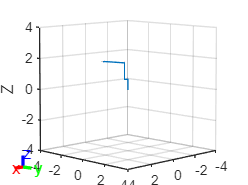


figure(3)
show(robot,homeConfiguration(robot));